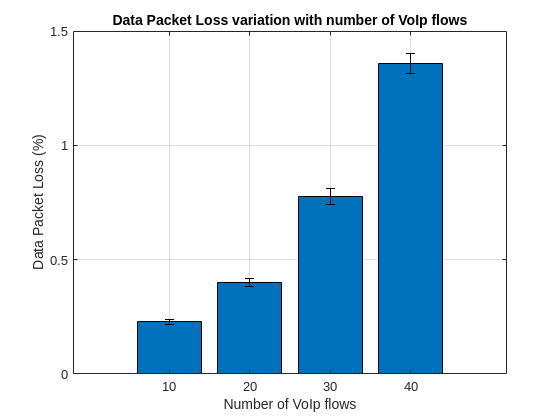

% a
N = 20;

lambda = 1500;
alfa = 0.1;
C = 10;
f = 10000;
P = 100000;
n = [10 20 30 40];

results = zeros(length(n), 7, 2);

for l=1:length(n)
    tmp = zeros(7, N);

    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i), ... 
         tmp(5, i), tmp(6, i), tmp(7, i)] = Simulator3(lambda, C, f, P, n(l));
    end

    for i=1:7
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

bar(n, results(:, 1, 1));
title("Data Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Data Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

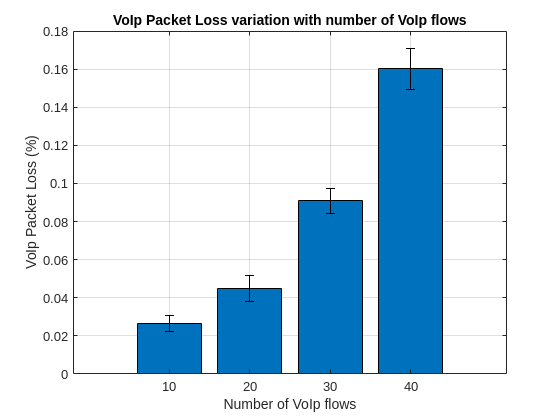


bar(n, results(:, 2, 1));
title("VoIp Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("VoIp Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

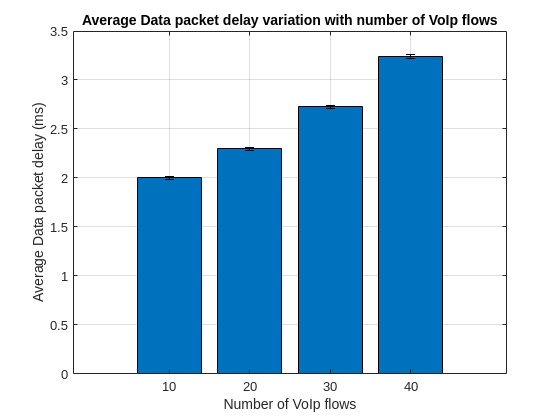


bar(n, results(:, 3, 1));
title("Average Data packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average Data packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 3, 1), results(:, 3, 2), results(:, 3, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

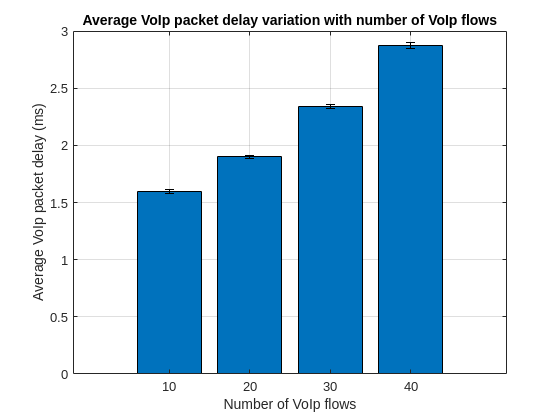


bar(n, results(:, 4, 1));
title("Average VoIp packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average VoIp packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 4, 1), results(:, 4, 2), results(:, 4, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

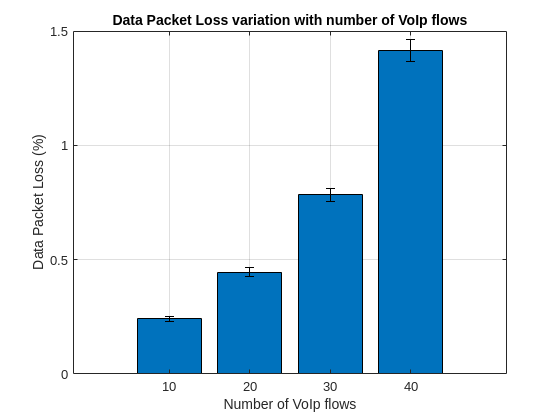

% b
N = 20;

lambda = 1500;
alfa = 0.1;
C = 10;
f = 10000;
P = 100000;
n = [10 20 30 40];

results = zeros(length(n), 7, 2);

for l=1:length(n)
    tmp = zeros(7, N);

    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i), ... 
         tmp(5, i), tmp(6, i), tmp(7, i)] = Simulator4(lambda, C, f, P, n(l));
    end

    for i=1:7
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

bar(n, results(:, 1, 1));
title("Data Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Data Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

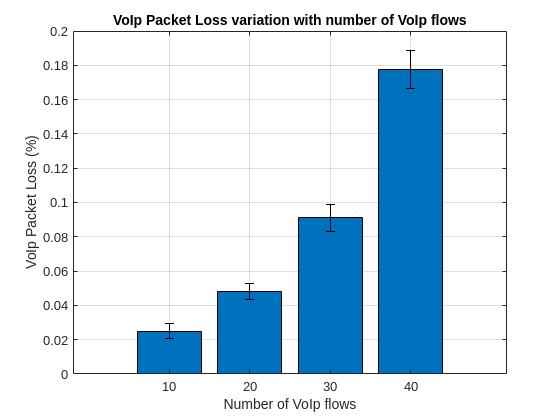


bar(n, results(:, 2, 1));
title("VoIp Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("VoIp Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

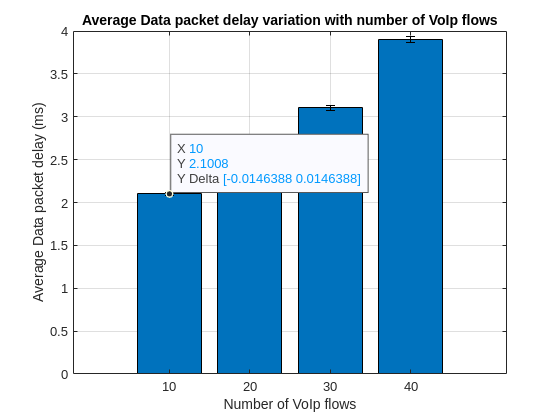


bar(n, results(:, 3, 1));
title("Average Data packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average Data packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 3, 1), results(:, 3, 2), results(:, 3, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

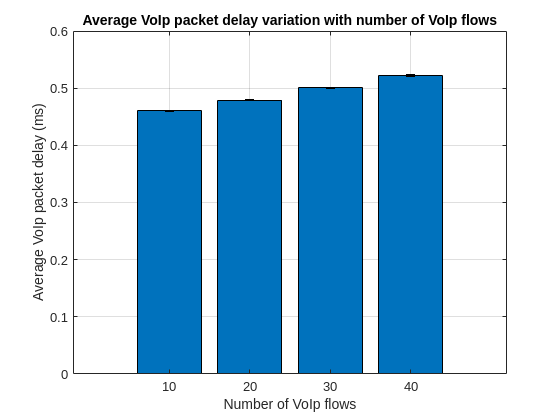


bar(n, results(:, 4, 1));
title("Average VoIp packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average VoIp packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 4, 1), results(:, 4, 2), results(:, 4, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

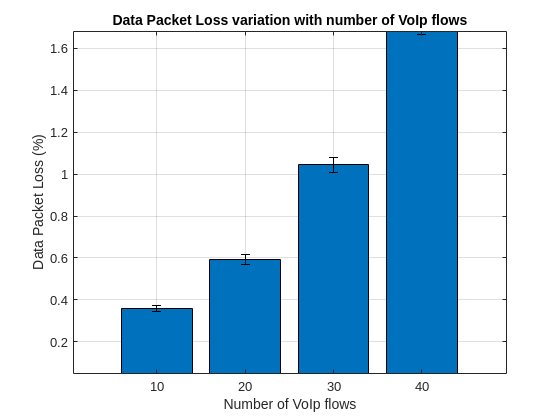

% c
N = 20;

lambda = 1500;
alfa = 0.1;
C = 10;
f = 10000;
P = 100000;
n = [10 20 30 40];

results = zeros(length(n), 7, 2);

for l=1:length(n)
    tmp = zeros(7, N);

    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i), ... 
         tmp(5, i), tmp(6, i), tmp(7, i)] = Simulator4A(lambda, C, f, P, n(l));
    end

    for i=1:7
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

bar(n, results(:, 1, 1));
title("Data Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Data Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

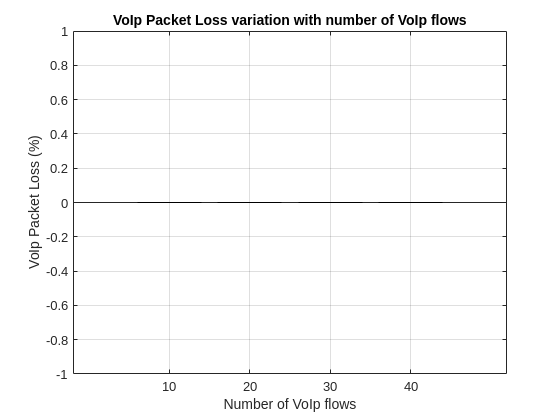


bar(n, results(:, 2, 1));
title("VoIp Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("VoIp Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

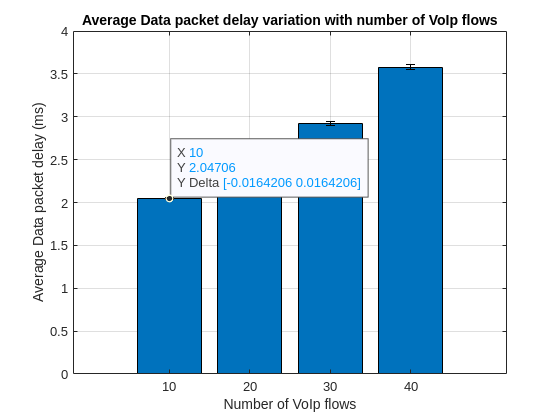


bar(n, results(:, 3, 1));
title("Average Data packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average Data packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 3, 1), results(:, 3, 2), results(:, 3, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

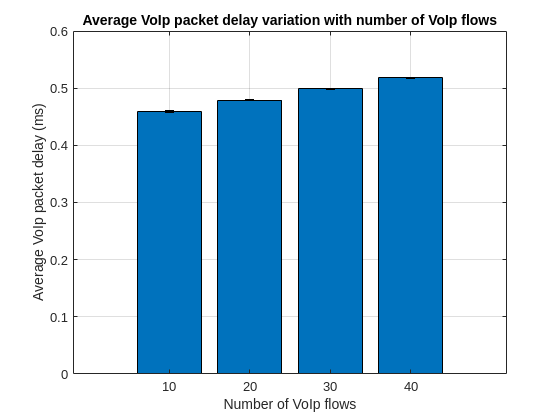


bar(n, results(:, 4, 1));
title("Average VoIp packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average VoIp packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 4, 1), results(:, 4, 2), results(:, 4, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

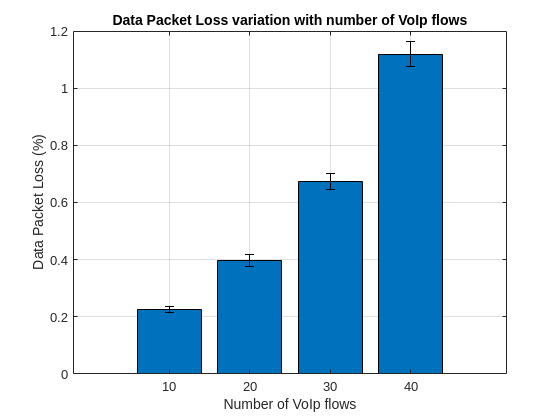

% d
N = 20;

lambda = 1500;
alfa = 0.1;
C = 10;
f = 10000;
P = 100000;
n = [10 20 30 40];

results = zeros(length(n), 7, 2);

for l=1:length(n)
    tmp = zeros(7, N);

    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i), ... 
         tmp(5, i), tmp(6, i), tmp(7, i)] = Simulator4B(lambda, C, f, P, n(l));
    end

    for i=1:7
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

bar(n, results(:, 1, 1));
title("Data Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Data Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

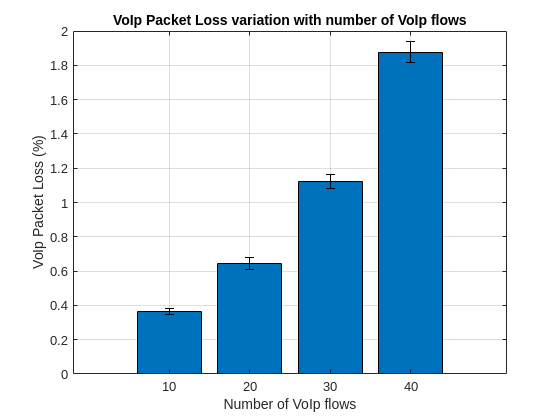


bar(n, results(:, 2, 1));
title("VoIp Packet Loss variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("VoIp Packet Loss (%)");
grid on;
hold on;
er = errorbar(n, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

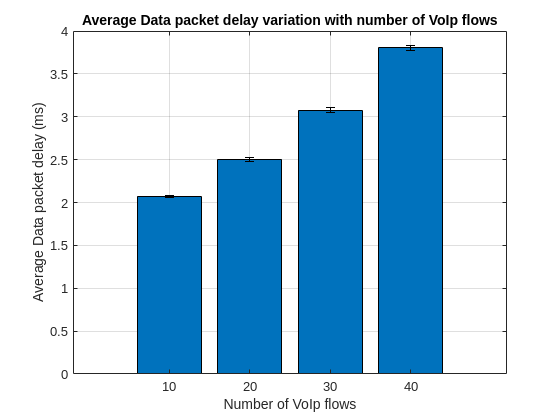


bar(n, results(:, 3, 1));
title("Average Data packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average Data packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 3, 1), results(:, 3, 2), results(:, 3, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

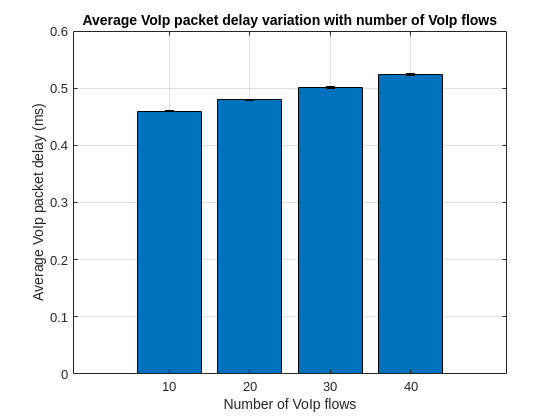


bar(n, results(:, 4, 1));
title("Average VoIp packet delay variation with number of VoIp flows");
xlabel("Number of VoIp flows");
ylabel("Average VoIp packet delay (ms)");
grid on;
hold on;
er = errorbar(n, results(:, 4, 1), results(:, 4, 2), results(:, 4, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;